%simulate Two 1D Random Walks and Compare Diffusion Coefficients

%Generate track_1 with step size = 1
numParticles = 1;
numSteps = 4000;
x = zeros(numParticles, numSteps); %initialize trajectory
for stepNumber = 2 : numSteps
    for p = 1 : numParticles
        xStep = 1 * sign(randn()); %step = +1 or -1
        x(p, stepNumber) = x(p, stepNumber - 1) + xStep; %update position
    end
end
track_1 = x;

%Generate track_2 with smaller step size = 0.1
numParticles = 1;
numSteps = 4000;
x = zeros(numParticles, numSteps); %initialize trajectory
for stepNumber = 2 : numSteps
    for p = 1 : numParticles
        xStep = 0.1 * sign(randn()); %smaller step
        x(p, stepNumber) = x(p, stepNumber - 1) + xStep; %update position
    end
end
track_2 = x;


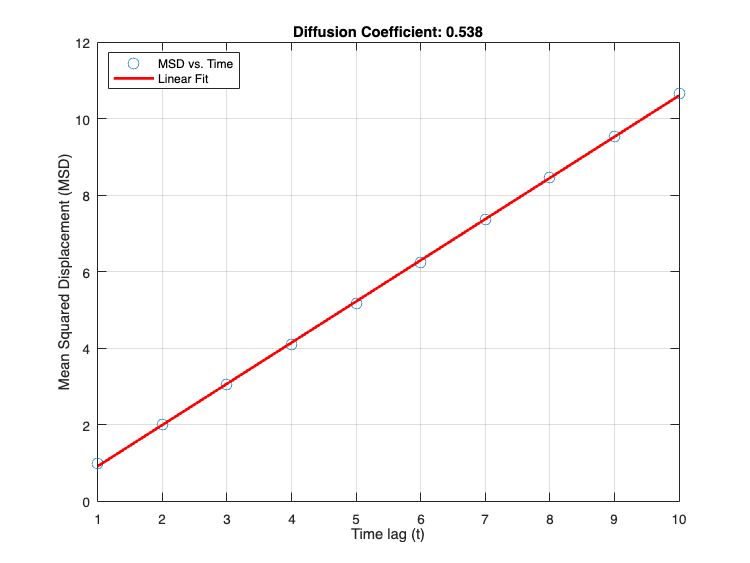



%Single Track MSD Analysis (track_1) ----

track = track_1; %pick track
lags = 1:10; %time lag values
msd = zeros(1, length(lags)); % init MSD array

for lag = lags
    displacements = track(:, lag+1:end) - track(:, 1:end-lag); % Δx
    squared_displacements = displacements.^2; %(Δx)^2
    msd(lag) = mean(squared_displacements(:)); %average
end

fit_result = polyfit(lags, msd, 1); %linear fit: MSD = 2Dt
diff_coefficient = fit_result(1) / 2; %extract D

%Plot MSD vs lag
figure;
plot(lags, msd, 'o', 'MarkerSize', 8);
hold on;
plot(lags, polyval(fit_result, lags), 'r-', 'LineWidth', 2);
xlabel('Time lag (t)');
ylabel('Mean Squared Displacement (MSD)');
legend('MSD vs. Time', 'Linear Fit', 'Location', 'northwest');
title(['Diffusion Coefficient: ' num2str(diff_coefficient,3)]);
grid on;
hold off;



%Compare MSDs of track_1 and track_2

%track 1 again
track = track_1;
lags = 1:10;
msd = zeros(1, length(lags));
for lag = lags
    displacements = track(:, lag+1:end) - track(:, 1:end-lag);
    squared_displacements = displacements.^2;
    msd(lag) = mean(squared_displacements(:));
end
fit_result = polyfit(lags, msd, 1);
diff_coefficient = fit_result(1) / 2;

%store results
lags_1 = lags;
msd_1 = msd;
fit_result_1 = fit_result;
diff_coefficient_1 = diff_coefficient;

%track 2
track = track_2;
lags = 1:10;
msd = zeros(1, length(lags));
for lag = lags
    displacements = track(:, lag+1:end) - track(:, 1:end-lag);
    squared_displacements = displacements.^2;
    msd(lag) = mean(squared_displacements(:));
end
fit_result = polyfit(lags, msd, 1);
diff_coefficient = fit_result(1) / 2;

%store results
lags_2 = lags;
msd_2 = msd;
fit_result_2 = fit_result;
diff_coefficient_2 = diff_coefficient;


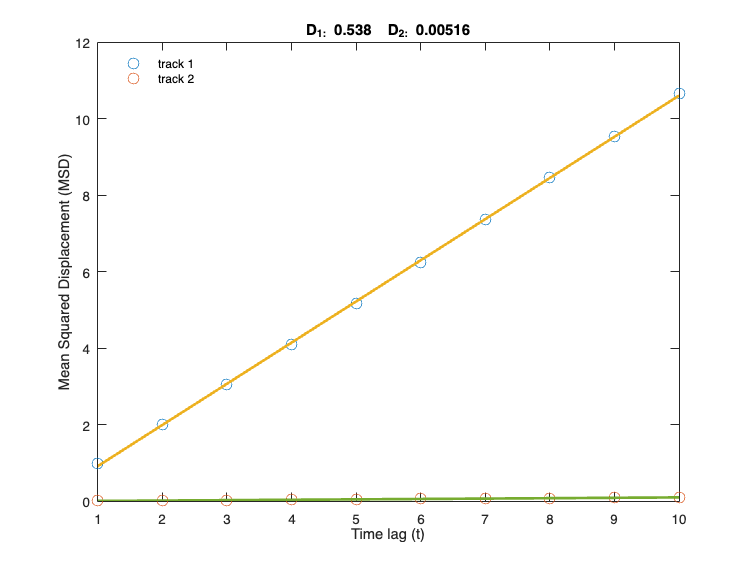

%plot both Tracks' MSDs

colors = lines; % color palette

figure;
hold on;
box on;
plot(lags_1, msd_1, 'o', 'MarkerSize', 8, 'Color', colors(1,:)); % track 1 MSD
plot(lags_2, msd_2, 'o', 'MarkerSize', 8, 'Color', colors(2,:)); % track 2 MSD
plot(lags_1, polyval(fit_result_1, lags_1), '-', 'LineWidth', 2, 'Color', colors(3,:)); % fit 1
plot(lags_2, polyval(fit_result_2, lags_2), '-', 'LineWidth', 2, 'Color', colors(5,:)); % fit 2
xlabel('Time lag (t)');
ylabel('Mean Squared Displacement (MSD)');
legend('track 1', 'track 2', 'Location', 'northwest', 'Box', 'off');
title(['D_1: ' num2str(diff_coefficient_1, 3) '  D_2: ' num2str(diff_coefficient_2, 3)]);